clear;
clc;

% setup
nx = 100;
dx = 2*pi/nx;
X = dx*(1:nx);

f = @(u) 0.5*u.^2; % flux function

u0 = (sin(X/2)).^2;
t0 = 0;
tf = 5;
CFL = 0.5;

% algorithm
u = u0;
t = t0;
U = u;
T = t;
while t < tf
    dt = CFL*dx/max(abs(u)); % compute dt (dynamic)

    F = zeros(size(u)); % cell interface flux

    % need to handle i==1 differently
    uL = u(end);
    uR = u(1);
    % solve riemann problem
    if uL > uR
        F(1) = f(uL);
    else
        F(1) = f(uR);
    end
    
    for i = 2:nx
        uL = u(i-1);
        uR = u(i);
        % solve riemann problem
        if uL > uR
            F(i) = uL;
        else
            F(i) = uR;
        end
    end
    
    % update using godunov
    u = u - dt/dx*(F-[F(end) F(1:end-1)]);
    t = t + dt;
    U = [U; u];
    T = [T; t];
end

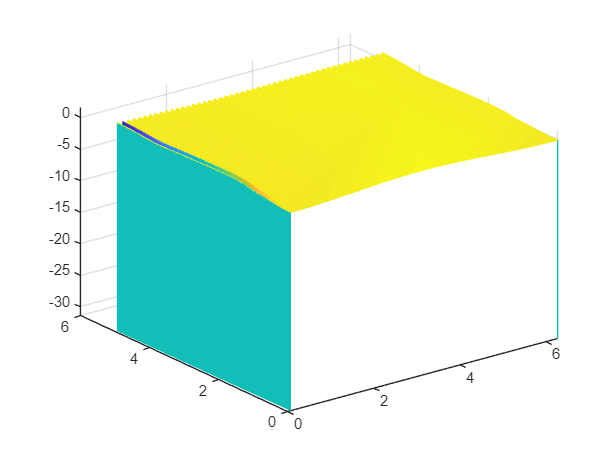

% plot
waterfall(X,T,U)